clc;clear;close all hidden;

Create a satellite scenario

startTime = datetime(2025,6,28,0,0,0);
stopTime = startTime + hours(12);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

Create the satellite orbit based on Keplerian elements

semimajoraxis = earthRadius + 400e3;
eccentricity = 0;
inclination = 45;
RAAN = 40;
argofperiapsis = 0;
trueanomaly = -60;
sat1 = satellite(sc,semimajoraxis,eccentricity,inclination,RAAN,argofperiapsis,trueanomaly,"Name","Satellite1");

Display the orbit

% play(sc)

Creating a ground station

lat=38.875941904578895;
lon=22.437526584061686;
minElevationAngle = 5;
gs = groundStation(sc,lat,lon,"MinElevationAngle",minElevationAngle,"Name","Lamia Base Station");

Satellite pass (access) analysis

ac = access(sat1,gs);
ac2 = access(gs,sat1);
accessIntervals(ac) 

ans = 3×8 table
       Source              Target           IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________    ____________________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite1"    "Lamia Base Station"          1           28-Jun-2025 08:06:00    28-Jun-2025 08:09:00      180           6            6    
    "Satellite1"    "Lamia Base Station"          2           28-Jun-2025 09:41:00    28-Jun-2025 09:48:00      420           7            7    
    "Satellite1"    "Lamia Base Station"          3           28-Jun-2025 11:18:00    28-Jun-2025 11:24:00      360           8    

accessIntervals(ac2)

ans = 3×8 table
           Source              Target       IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ____________________    ____________    ______________    ____________________    ____________________    ________    __________    ________

    "Lamia Base Station"    "Satellite1"          1           28-Jun-2025 08:06:00    28-Jun-2025 08:09:00      180           6            6    
    "Lamia Base Station"    "Satellite1"          2           28-Jun-2025 09:41:00    28-Jun-2025 09:48:00      420           7            7    
    "Lamia Base Station"    "Satellite1"          3           28-Jun-2025 11:18:00    28-Jun-2025 11:24:00      360           8    

Position information of the satellite

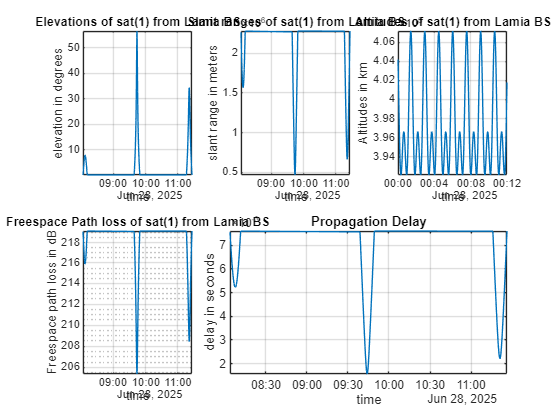

time = startTime;
elevations = [];
ranges = [];
time_axis = [];

while time ~= stopTime
    [az,el,r] = aer(gs,sat1,time);
    % the data must be cleaned.
    % negative elevations are below the horizon.
    % keep only the positive angles
    if el >= 0    
        time_axis = [time_axis time];
        elevations = [elevations el];
        ranges = [ranges r];
    end
    time = time + seconds(1);
end

positions = states(sat1,'CoordinateFrame','geographic');
alts = positions(3,:);

%   calculate the altitude of each elevation
subplot(2,3,1);
plot(time_axis,elevations);
title('Elevations of sat(1) from Lamia BS');
xlabel('time');
ylabel('elevation in degrees');
grid on;
axis tight;

subplot(2,3,2);
plot(time_axis,ranges);
grid on;
axis tight;
xlabel('time');
ylabel('slant range in meters');
title('Slant ranges of sat(1) from Lamia BS')

subplot(2,3,3);
time_axis2 = sc.StartTime + seconds(0:length(alts)-1);  % Time vector
plot(time_axis2,alts);
grid on;
axis tight;
xlabel('time');
ylabel('Altitudes in km');
title('Altitudes of sat(1) from Lamia BS')

% Calculate pathloss for each slant range
fc = 30e9; % 30 GHz
FSPL_dB = 20*log10(ranges) + 20*log10(fc) - 147.55;
FSPL_dBm = FSPL_dB + 30;
subplot(2,3,4);
semilogy(time_axis, FSPL_dBm);
grid on;
axis tight;
xlabel('time');
ylabel('Freespace path loss in dB');
title('Freespace Path loss of sat(1) from Lamia BS');

c = 3e8;
%   calculation of delays
propagationDelay = ranges/c;
subplot(2,3,[5 6]);
plot(time_axis,propagationDelay);
grid on;
axis tight;
xlabel('time');
ylabel('delay in seconds');
title('Propagation Delay');